# Figure of PCC K vs S

Get the data for a figure bar plot with results of permutation DFA for males and feamles separately at 50PC

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
UGroup = unique(TmicAll7);
load(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'),'PC_val')
Mat_PCC_mean = nan(2*(length(UGroup)+1),2);
Mat_PCC_std = nan(2*(length(UGroup)+1),2);
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('Data4_DeafBats_PermDFA_AcGroup%d.mat', GR)), 'L_males', 'L_females', 'Lperm_males', 'Lperm_females',  'NPC_opt_males', 'NPC_opt_females')
    
    Mat_PCC_mean(GR*2-1,1) = mean((1-L_males(:,PC_val == NPC_opt_males)).*100);
    Mat_PCC_mean(GR*2-1,2) = mean((1-Lperm_males(:,PC_val == NPC_opt_males)).*100);
    Mat_PCC_mean(GR*2,1) = mean((1-L_females(:,PC_val == NPC_opt_females)).*100);
    Mat_PCC_mean(GR*2,2) = mean((1-Lperm_females(:,PC_val == NPC_opt_females)).*100);
    Mat_PCC_std(GR*2-1,1) = std((1-L_males(:,PC_val == NPC_opt_males)).*100);
    Mat_PCC_std(GR*2-1,2) = std((1-Lperm_males(:,PC_val == NPC_opt_males)).*100);
    Mat_PCC_std(GR*2,1) = std((1-L_females(:,PC_val == NPC_opt_females)).*100);
    Mat_PCC_std(GR*2,2) = std((1-Lperm_females(:,PC_val == NPC_opt_females)).*100);
end


load(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'), 'L_males', 'L_females', 'Lperm_males', 'Lperm_females', 'NPC_opt_males', 'NPC_opt_females','PC_val')
GR=8;
Mat_PCC_mean(GR*2-1,1) = mean((1-L_males(:,PC_val == NPC_opt_males)).*100);
Mat_PCC_mean(GR*2-1,2) = mean((1-Lperm_males(:,PC_val == NPC_opt_males)).*100);
Mat_PCC_mean(GR*2,1) = mean((1-L_females(:,PC_val == NPC_opt_females)).*100);
Mat_PCC_mean(GR*2,2) = mean((1-Lperm_females(:,PC_val == NPC_opt_females)).*100);
Mat_PCC_std(GR*2-1,1) = std((1-L_males(:,PC_val == NPC_opt_males)).*100);
Mat_PCC_std(GR*2-1,2) = std((1-Lperm_males(:,PC_val == NPC_opt_males)).*100);
Mat_PCC_std(GR*2,1) = std((1-L_females(:,PC_val == NPC_opt_females)).*100);
Mat_PCC_std(GR*2,2) = std((1-Lperm_females(:,PC_val == NPC_opt_females)).*100);


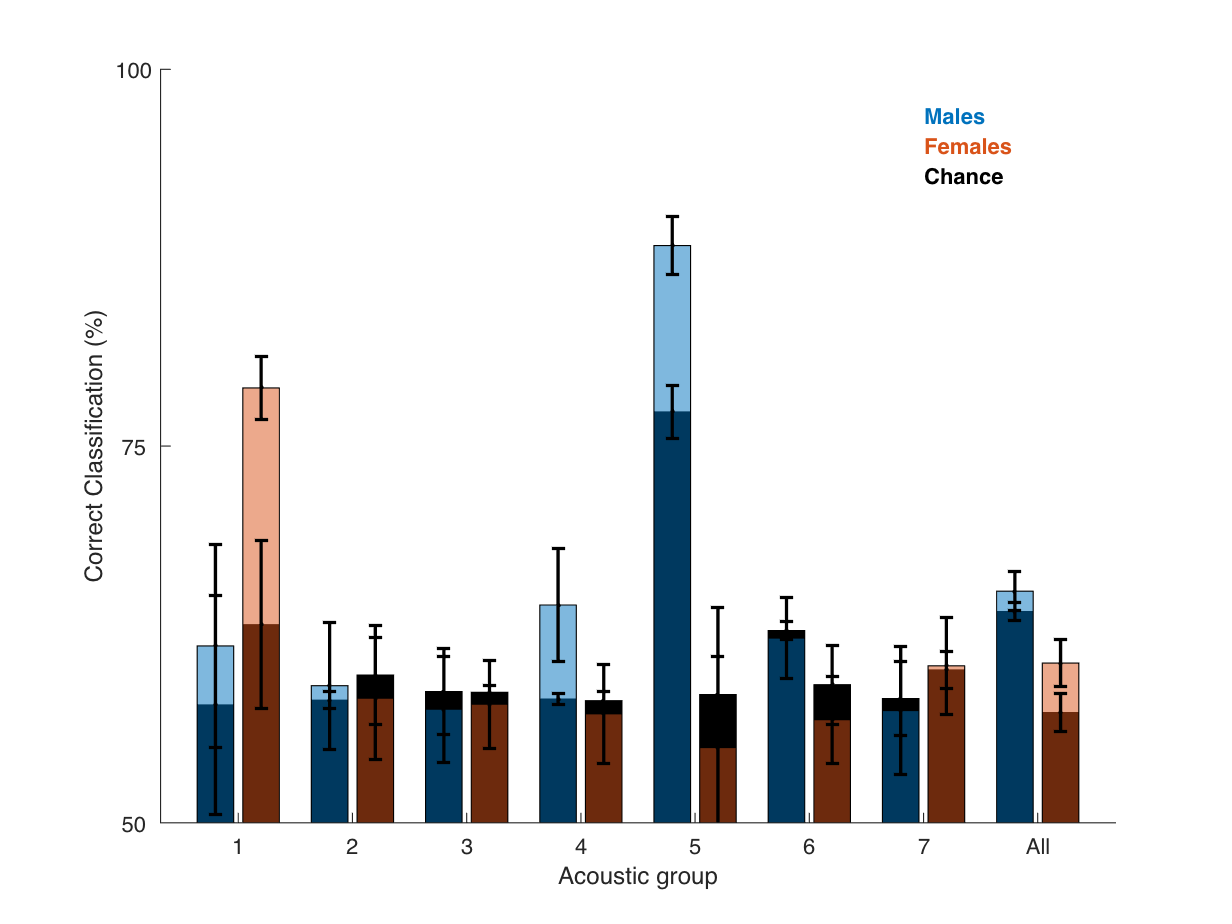


figure()
GR = length(UGroup);
X = reshape([1:GR+1; 1:GR+1] + repmat([-0.2;0.2], 1, GR+1), 1,(GR+1)*2);
bar(X,Mat_PCC_mean(:,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(:,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],8,1);
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(7,93,'Chance','color','k', 'FontWeight', 'bold')
hold off

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
UGroup = unique(TmicAll7);
load(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'),'PC_val')
Mat_PCC_mean = nan(2*(length(UGroup)+1),2);
Mat_PCC_std = nan(2*(length(UGroup)+1),2);
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('Data4_DeafBats_PermDFA_AcGroup%d.mat', GR)), 'L_males', 'L_females', 'Lperm_males', 'Lperm_females')
    
    Mat_PCC_mean(GR*2-1,1) = mean((1-L_males(:,end)).*100);
    Mat_PCC_mean(GR*2-1,2) = mean((1-Lperm_males(:,end)).*100);
    Mat_PCC_mean(GR*2,1) = mean((1-L_females(:,end)).*100);
    Mat_PCC_mean(GR*2,2) = mean((1-Lperm_females(:,end)).*100);
    Mat_PCC_std(GR*2-1,1) = std((1-L_males(:,end)).*100);
    Mat_PCC_std(GR*2-1,2) = std((1-Lperm_males(:,end)).*100);
    Mat_PCC_std(GR*2,1) = std((1-L_females(:,end)).*100);
    Mat_PCC_std(GR*2,2) = std((1-Lperm_females(:,end)).*100);
end

load(fullfile(LocalDataDir, 'Data4_DeafBats_PermDFA_AllCalls.mat'), 'L_males', 'L_females', 'Lperm_males', 'Lperm_females')
GR=8;
Mat_PCC_mean(GR*2-1,1) = mean((1-L_males(:,end)).*100);
Mat_PCC_mean(GR*2-1,2) = mean((1-Lperm_males(:,end)).*100);
Mat_PCC_mean(GR*2,1) = mean((1-L_females(:,end)).*100);
Mat_PCC_mean(GR*2,2) = mean((1-Lperm_females(:,end)).*100);
Mat_PCC_std(GR*2-1,1) = std((1-L_males(:,end)).*100);
Mat_PCC_std(GR*2-1,2) = std((1-Lperm_males(:,end)).*100);
Mat_PCC_std(GR*2,1) = std((1-L_females(:,end)).*100);
Mat_PCC_std(GR*2,2) = std((1-Lperm_females(:,end)).*100);


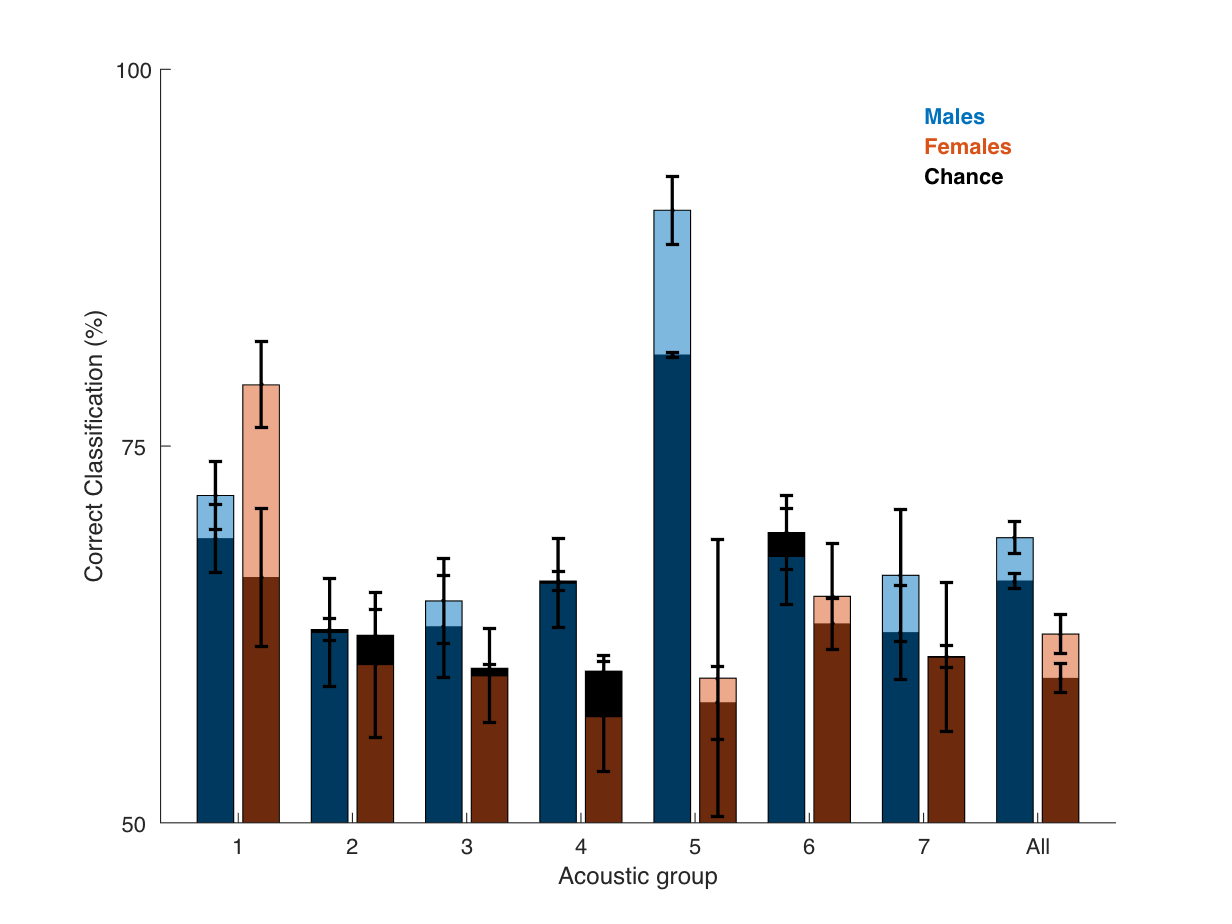


figure()
GR = length(UGroup);
X = reshape([1:GR+1; 1:GR+1] + repmat([-0.2;0.2], 1, GR+1), 1,(GR+1)*2);
bar(X,Mat_PCC_mean(:,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(:,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],8,1);
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([50 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(7,93,'Chance','color','k', 'FontWeight', 'bold')
hold off